% mikexcohen@gmail.com

## Compute and plot TF-ITPC for one electrode

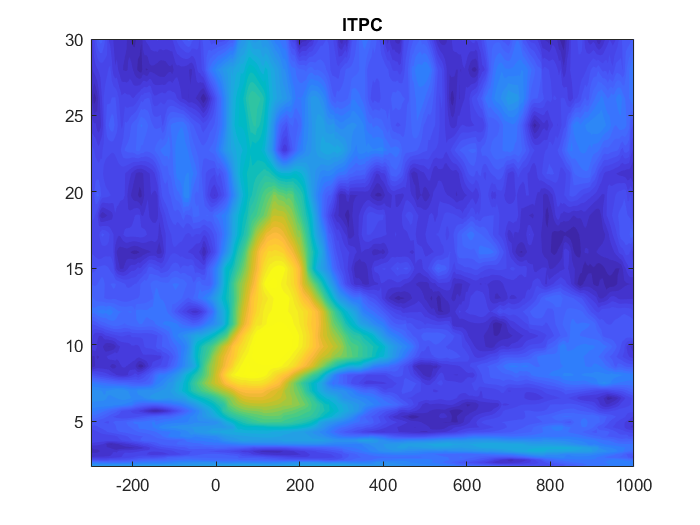

load sampleEEGdata.mat

% wavelet parameters
num_frex = 40;
min_freq =  2;
max_freq = 30;

channel2use = 'pz';

% set range for variable number of wavelet cycles
range_cycles = [ 4 10 ];

% other wavelet parameters
frex = logspace(log10(min_freq),log10(max_freq),num_frex);
wavecycles = logspace(log10(range_cycles(1)),log10(range_cycles(end)),num_frex);
time = -2:1/EEG.srate:2;
half_wave_size = (length(time)-1)/2;

% FFT parameters
nWave = length(time);
nData = EEG.pnts*EEG.trials;
nConv = nWave+nData-1;


% FFT of data (doesn't change on frequency iteration)
dataX = fft( reshape(EEG.data(strcmpi(channel2use,{EEG.chanlocs.labels}),:,:),1,nData) ,nConv);

% initialize output time-frequency data
tf = zeros(num_frex,EEG.pnts);

% loop over frequencies
for fi=1:num_frex
    
    % create wavelet and get its FFT
    s = wavecycles(fi)/(2*pi*frex(fi));
    wavelet  = exp(2*1i*pi*frex(fi).*time) .* exp(-time.^2./(2*s^2));
    waveletX = fft(wavelet,nConv);
    
    % run convolution
    as = ifft(waveletX.*dataX,nConv);
    as = as(half_wave_size+1:end-half_wave_size);
    as = reshape(as,EEG.pnts,EEG.trials);
    
    % compute ITPC
    tf(fi,:) = abs(mean(exp(1i * angle(as)), 2));
    % average over the 2nd dim. (trials), 
    % not average over time pts within each trails.
end

% plot results
figure(1), clf
contourf(EEG.times,frex,tf,40,'linecolor','none')
set(gca,'clim',[0 .6],'ydir','normal','xlim',[-300 1000])
title('ITPC')

## illustration of ITPC with different variances

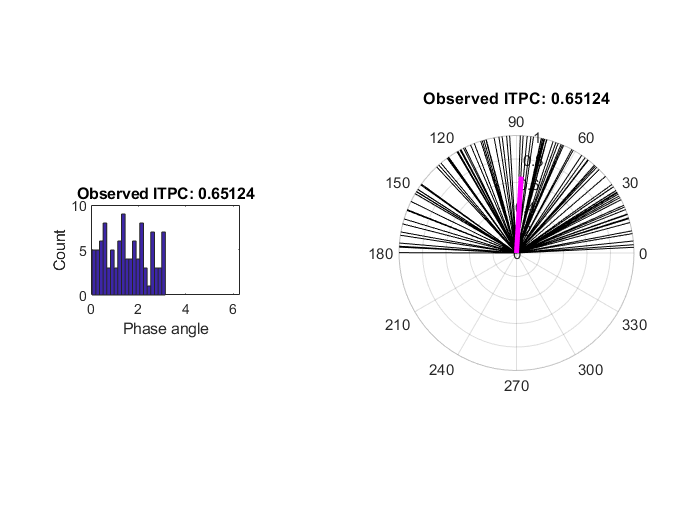

% specify parameters
circ_prop = .5; % proportion of the circle to fill
N = 100; % number of "trials"

% generate phase angle distribution
simdata = rand(1,N) * (2*pi) * circ_prop;


% compute ITPC and preferred phase angle
itpc      = abs(mean(exp(1i*simdata)));
prefAngle = angle(mean(exp(1i*simdata)));


% and plot...
figure(2), clf

% as linear histogram
subplot(3,3,4)
hist(simdata,20)
xlabel('Phase angle'), ylabel('Count')
set(gca,'xlim',[0 2*pi])
title([ 'Observed ITPC: ' num2str(itpc) ])

% and as polar distribution
subplot(1,2,2)
polarplot([zeros(1,N); simdata],[zeros(1,N); ones(1,N)],'k')
hold on
h = polarplot([0 prefAngle],[0 itpc],'m');
set(h,'linew',3)
title([ 'Observed ITPC: ' num2str(itpc) ])

## end.